clear;
M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;
f = 0;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
C_ = C(2,:)

C_ =      0     0     1     0


D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];



x_0 = [0.01; 0.01; 0.01; 0.01];
x_h0 = [0; 0; 0; 0];

%========Фильтр Калмана=====

QL = [0.1 0 0 0;
    0 0.1 0 0;
    0 0 0.1 0;
    0 0 0 0.1];
RL = [0.01 0; 0 0.01];

[PL,~,Kx] = icare(A', C', QL, RL, 0, eye(4), 0);

disp("Determinant of PL");

Determinant of PL


disp(det(PL));

   3.1823e-05




disp("PL");

PL


disp(PL);

    0.0404    0.0317    0.0006    0.0016
    0.0317    0.1282    0.0040    0.0103
    0.0006    0.0040    0.0591    0.1248
    0.0016    0.0103    0.1248    0.3926




L = -PL* C' * pinv(RL);

disp("L");

L


disp(L);

   -4.0417   -0.0563
   -3.1691   -0.3975
   -0.0563   -5.9121
   -0.1632  -12.4782



disp("A+LC checking");

A+LC checking


disp(eig(A+L*C));

   -4.4057
   -2.9772
   -1.0614
   -1.5095







%========LQR=======================
Q = [10 0 0 0; 0 10 0 0; 0 0 10 0; 0 0 0 10];
R = 1;
nu = 1;

[P1,~,Ky] = icare(A, B, Q, R, [], [], [], nu);

disp("Determinant of P1");

Determinant of P1


disp(det(P1));

   1.2463e+13




disp("P1");

P1


disp(P1);

   1.0e+06 *

    0.0001    0.0010   -0.0075   -0.0031
    0.0010    0.0130   -0.1019   -0.0427
   -0.0075   -0.1019    6.7720    2.8067
   -0.0031   -0.0427    2.8067    1.1633




K = - inv(R) * B' * P1;
disp("K");

K


disp(K);

   1.0e+03 *

    0.0032    0.0443   -5.7208   -2.3693



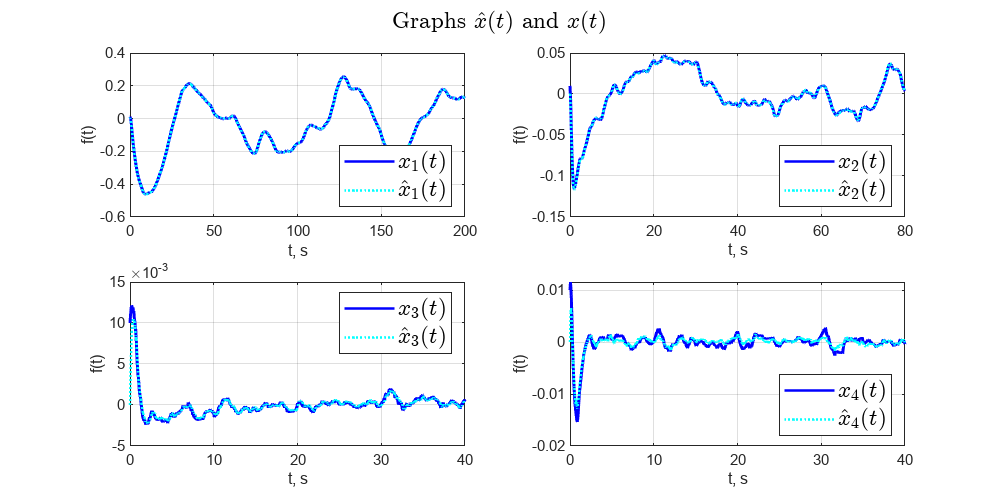



[t, x] = ode45(@(t,x) sys_wrapper_kalman(t,x,K,L,C,m,M,l,g,A,B), ...
             [0 200], [x_0; x_h0]);
%{
plot(t, x(:, 1)-x(:, 5), 'b-')
hold on
plot(t, x(:, 2)-x(:, 6), 'm:')
plot(t, x(:, 3)-x(:, 7), 'g:')
plot(t, x(:, 4)-x(:, 8), 'k:')
%plot(t, x(:, 5), 'm:')
%}


%{
tspan = [0 90];

[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

disp('phi');
max_phi = max(x(:,3))
min(x(:,3))
disp('a');
max_a = max(x(:,1))
min(x(:,1))
disp('u');
max_u = max( u)
min(u)
%}

% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:, 1), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x(:,5), 'c:', 'LineWidth',1.5); 
legend('$x_1(t)$','$\hat{x}_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 90])
grid()
hold off

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:, 2), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x(:,6), 'c:', 'LineWidth',1.5); 
legend('$x_2(t)$','$\hat{x}_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 80])
grid()
hold off

subplot(2,2,3);
plot(t, x(:, 3), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x(:,7), 'c:', 'LineWidth',1.5); 
legend('$x_3 (t)$','$\hat{x}_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 40])
grid()
hold off

subplot(2,2,4);
plot(t, x(:, 4), 'b-', 'LineWidth',1.5);
hold on
plot(t, x(:,8), 'c:', 'LineWidth',1.5); 
legend('$x_4(t)$', '$\hat{x}_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 40])
grid()
hold off


sgtitle('Graphs $ \hat{x}(t)$ and $x(t)$','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\6_kalm_x_1.png'];
exportgraphics(gcf, full_path, 'Resolution', 300);